# Algoritmo de Chirp Scaling ET-291

Alunos

DOUGLAS MASSAHIRO KOTSUBO

GUSTAVO HENRIQUE DE QUEIROZ STABILE

RODRIGO DE LIMA FLORINDO

## Aplicação do algoritmo de chirp scaling para alvos pontuais

Seguindo o mesmo procedimento realizado no relatório passado, iremos primeiro validar o uso do CSA para alvos pontuais, antes de aplica-lo em dados brutos reais.

% Inicialização do código limpando o workspace, a janela de comandos e 
% fechando todas a janelas abertas.
clear; clc; close all;

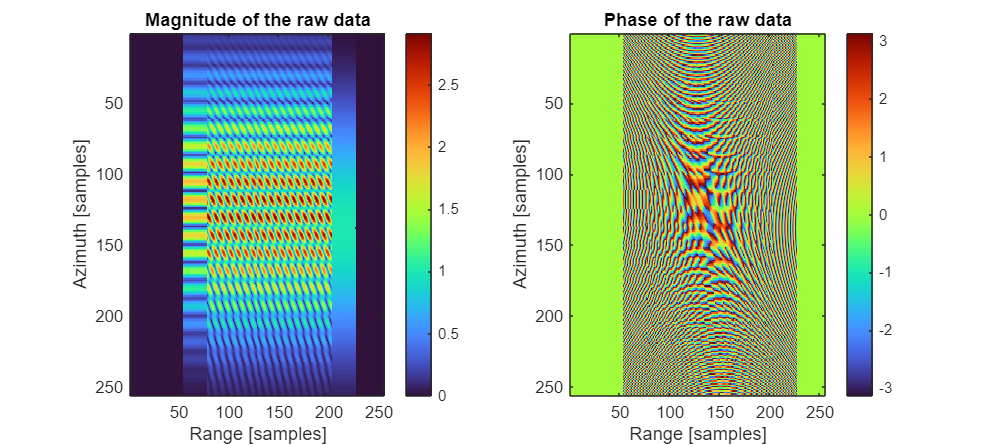

% Execução do código de geração de dados brutos sintéticos para alvos
% pontuais
run("Parametros_alvo_pontual.m");

% Exibição da Magnitude e da Fase dos dados brutos gerados
figure('Position',[0,0,900,400]);
subplot(1,2,1);
imagesc(abs(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Magnitude of the raw data')
subplot(1,2,2);
imagesc(angle(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Phase of the raw data');

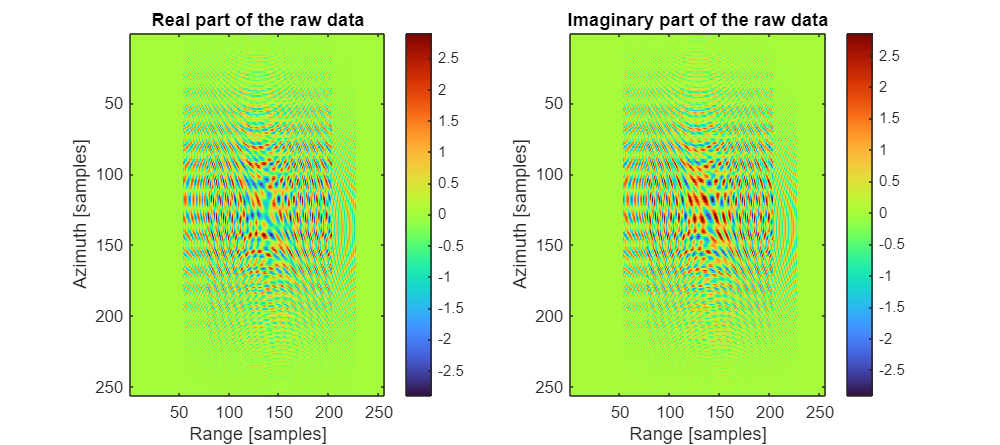


% Exibição das partes reais e imaginárias dos dados brutos sintéticos
figure('Position',[0,0,900,400]);
subplot(1,2,1);
imagesc(real(s0_upchirp));
colorbar;
colormap('turbo');
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Real part of the raw data') 
subplot(1,2,2);
imagesc(imag(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Imaginary part of the raw data');